# Joint Probabilistic Data Association Filter

This script applies a JPDA Filter to various examples. Some with simulated data, some with real-life applications such as estimation of traffic participants.

## Parameters

The following parameters have to be set for the JPDA Filter. They depend on the problem at hand. For this case, it is assumed that all targets will share the same dynamical model. The dynamical model is of the form:

x[k+1] = F*x[k] + G*u[k] + w[k]

z[k] = H*x[k] + v[k]

Here w is process noise with variance R and v is measurement noise with variance Q. Furthermore, in the measurement model it is assumed that there is a probability P_D that a target is detected, and a probability of P_FA of a false alarm measurement being made. In the case of a false alarm, the measurement is uniformly distributed over the complete map.

clear, clc

global F            % F matrix of dynamical model
global G            % G matrix of dynamical model
global H            % H matrix of measurement model
global R            % Covariance matrix of motion model | dimStates X dimStates
global Q            % Covariance matrix of measurement model | dimStates X dimStates
global tau          % Number of targets
global P_D          % Probability of a detection
global P_FA         % Probability of a false alarm
global map_size     % size for the map, centered around the origin | scalar

% Variables for N/M heuristic
global N            % How many samples to take before evaluation
global M_P          % Treshold for promotion
global M_D          % Treshold for demotion
global DeltaMax     % Max distance between first and second measurement for track birth

## 1D Random Walk Simulation

### Initialise

First we will define the dynamical model, measurement model, and the JPDA Filter parameters. Also the initial estimates and ground truth have to be set for each target.

% Number of targets
tau = 3;

% Simulation duration
delta_t = 0.1;      % [s] Time between simulation steps
end_time = 100;     % [s] Duration of simulation
n_timesteps = end_time/delta_t + 1;

% Define dynamical model
n_states = 1;              % Number of states of the dynamics model.
n_inp    = 1;              % Number of control inputs.
n_meas   = 1;              % Number of states of a measurement.
F = eye(n_states);
G = ones(n_states, n_inp);
H = eye(n_meas, n_states);

% Set values for JPDA parameters
R = 0.02*eye(n_states);
Q = 0.02*eye(n_meas);
P_D = 0.9;
P_FA = 0.1;

% Set the bounds of the map
map_size = 6;

% Initialise arrays to store each timestep for plotting
ground_truth = zeros(n_states,tau,n_timesteps);
mu = zeros(n_states,tau,n_timesteps);
sigma = zeros(n_states,n_states,tau,n_timesteps);
% Cell arrays can have variable lengths for each timestep
z = cell(n_timesteps,1); 
association_ground_truth = cell(n_timesteps,1);

% Set initial estimate of target states
mu(:,:,1) = map_size*(rand(n_states, tau)-0.5);

% Set initial estimate of covariances. Increase to start with less certainty
sigma(:,:,:,1) = repmat(1*R,[1,1,tau]);

% Sample a ground truth for each target
for t = 1:tau
    ground_truth(:,t,1) = mvnrnd(mu(:,t,1),sigma(:,:,t,1));
end

### Run

Here we run the simulation. For each time-step, we simulate a ground truth and measurements, then the iterate() function performs an iteration of the JPDA filter. Since it is a random-walk, we don't have any inputs.

for timestep = 2:n_timesteps
    % Retrieve u (0 for a random walk)
    u = zeros(n_inp,tau);
    
    % Simulate dynamical model
    [ground_truth(:,:,timestep)] = simulate_dynamics(ground_truth(:,:,timestep-1), u);

    % Simulate measurements
    [z{timestep}, association_ground_truth{timestep}] = simulate_measurements(ground_truth(:,:,timestep));
    
    % Do an iteration of JPDA Filter
    [mu(:,:,timestep), sigma(:,:,:,timestep)] = iterate(mu(:,:,timestep-1), sigma(:,:,:,timestep-1), u, z{timestep});
end

### Visualize results

Visualization for a 1D Random walk. Since it is only 1D, we can plot the states overtime.

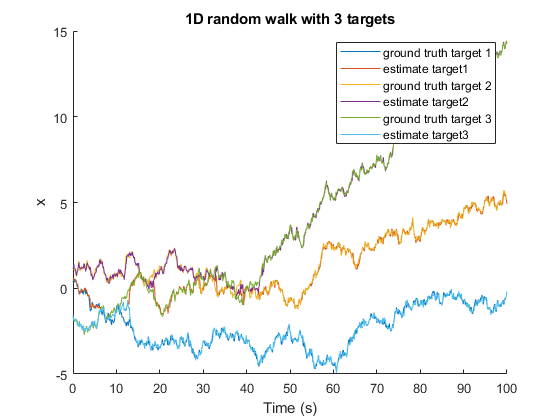

timesteps = 0:delta_t:end_time;

figure(1), clf(1), hold on
legendstrings = [];
for t = 1:tau
    plot(timesteps,squeeze(ground_truth(1,t,:)))
    plot(timesteps,squeeze(mu(1,t,:)))
    legendstrings = [legendstrings, "ground truth target " + num2str(t), "estimate target" + num2str(t)];
end
xlabel("Time (s)");
ylabel("x");
title("1D random walk with " + num2str(tau) + " targets");
legend(legendstrings)
hold off

## 2D Random Walk Simulation

### Initialise

We will have a slightly different dynamical model now because our random walk is 2-dimensional. Also, measurement noise is a bit increased and more false alarms are generated

% Number of targets
tau = 3;

% Simulation duration
delta_t = 0.1;      % [s] Time between simulation steps
end_time = 20;      % [s] Duration of simulation
n_timesteps = end_time/delta_t + 1;

% Define dynamical model
n_states = 2;              % Number of states of the dynamics model.
n_inp    = 1;              % Number of control inputs.
n_meas   = 2;              % Number of states of a measurement.
F = eye(n_states);
G = ones(n_states, n_inp);
H = eye(n_meas, n_states);

% Set values for JPDA parameters
R = 0.02*eye(n_states);
Q = 0.2*eye(n_meas);
P_D = 0.9;
P_FA = 0.25;

% Set the bounds of the map
map_size = 6;

% Initialise arrays to store each timestep for plotting
ground_truth = zeros(n_states,tau,n_timesteps);
mu = zeros(n_states,tau,n_timesteps);
sigma = zeros(n_states,n_states,tau,n_timesteps);
% Cell arrays can have variable lengths for each timestep
z = cell(n_timesteps,1); 
association_ground_truth = cell(n_timesteps,1);
beta = cell(n_timesteps,1);

% Set initial estimate of target states
mu(:,:,1) = map_size*(rand(n_states, tau)-0.5);

% Set initial estimate of covariances. Increase to start with less certainty
sigma(:,:,:,1) = repmat(1*R,[1,1,tau]);

% Sample a ground truth for each target
for t = 1:tau
    ground_truth(:,t,1) = mvnrnd(mu(:,t,1),sigma(:,:,t,1));
end


### Run

for timestep = 2:n_timesteps
    % Retrieve u (0 for a random walk)
    u = zeros(n_inp,tau);
    
    % Simulate dynamical model
    [ground_truth(:,:,timestep)] = simulate_dynamics(ground_truth(:,:,timestep-1), u);

    % Simulate measurements
    [z{timestep}, association_ground_truth{timestep}] = simulate_measurements(ground_truth(:,:,timestep));
    
    % Do an iteration of JPDA Filter
    [mu(:,:,timestep), sigma(:,:,:,timestep), beta{timestep}] = iterate(mu(:,:,timestep-1), sigma(:,:,:,timestep-1), u, z{timestep});
end


### Visualise results

Since we now have 2D states, we can make a video of the ground truths and estimates. Furthermore, in this video we can include the estimation uncertainties, the association probabilities, and the measurements with their ground truth association. 

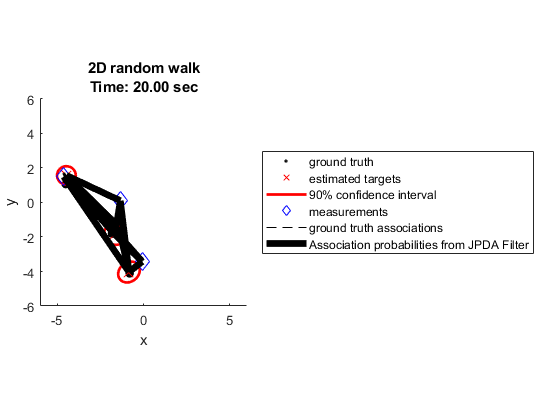

% Select what to include into the plotting
include_uncertainties = true;
include_association_probabilities = true;
include_measurements = true;
include_ground_truth_association = true;

% Initialise figure
figure(2), clf(2), hold on
title(sprintf('2D random walk\nTime: %0.2f sec', 0));
xlabel("x");
ylabel("y");
xlim([-map_size, map_size])
ylim([-map_size, map_size])
axis equal

% Plotting first iteration
% Plot ground truth
gt_plot = scatter(ground_truth(1,:,1), ground_truth(2,:,1),500,'.','black');
% Plot estimates
mu_plot = scatter(mu(1,:,1), mu(2,:,1),100,'x','red');
if include_uncertainties
    XData = zeros(100,tau);
    YData = zeros(100,tau);
    for t = 1:tau
        [XData(:,t), YData(:,t)] = plotErrorEllipse(mu(:,t,1), sigma(:,:,t,1),0.9);
    end
    sigma_plot = plot(XData,YData,'LineWidth',2,'Color',[1, 0, 0, 0.3]);
end
% Plot measurements (empty, first timestep has no measurements)
if include_measurements
    z_plot = scatter([], [],100,'d','blue');
end
% Plot ground truth associations (empty, first timestep has no measurements)
if include_ground_truth_association
    gt_associations_plot = plot(zeros(2,tau), zeros(2,tau), '--k', 'LineWidth', 0.5);
end
% Plot association probabilities (empty, first timestep has no measurements)
if include_association_probabilities
    % Initialised with a max of allocate*tau measurements, so it might break with bad luck
    allocate = 5;
    beta_plot = plot(zeros(2,allocate*tau*tau), zeros(2,allocate*tau*tau), '-k', 'LineWidth', 5);
end
% Set legend
legend([gt_plot, mu_plot, sigma_plot(1), z_plot, gt_associations_plot(1), beta_plot(1)],{'ground truth','estimated targets','90% confidence interval','measurements','ground truth associations','Association probabilities from JPDA Filter'},'Location','eastoutside')


% Iterating through the time array
for timestep = 2:n_timesteps
    % Update title
    title(sprintf('2D random walk\nTime: %0.2f sec', delta_t*(timestep-1)));
    
    % Update ground truth
    set(gt_plot, 'XData', ground_truth(1,:,timestep));
    set(gt_plot, 'YData', ground_truth(2,:,timestep));
    % Update estimates
    set(mu_plot, 'XData', mu(1,:,timestep));
    set(mu_plot, 'YData', mu(2,:,timestep));
    if include_uncertainties
        XData = zeros(100,tau);
        YData = zeros(100,tau);
        for t = 1:tau
            [XData(:,t), YData(:,t)] = plotErrorEllipse(mu(:,t,timestep), sigma(:,:,t,timestep),0.9);
        end
        set(sigma_plot, {'XData'}, mat2cell(XData',ones(1,tau),100))
        set(sigma_plot, {'YData'}, mat2cell(YData',ones(1,tau),100))
    end
    % Update measurements
    if include_measurements
        set(z_plot, 'XData',z{timestep}(1,:));
        set(z_plot, 'YData',z{timestep}(2,:));
    end
    % Update ground truth associations
    if include_ground_truth_association
        XData = zeros(2,tau);
        YData = zeros(2,tau);
        % Remove clutter measurements, those have no truth association
        filtered = association_ground_truth{timestep} ~= 0;
        XData(:,1:sum(filtered)) = [z{timestep}(1,filtered);
                                    ground_truth(1,association_ground_truth{timestep}(filtered),timestep)];
        YData(:,1:sum(filtered)) = [z{timestep}(2,filtered);
                                    ground_truth(2,association_ground_truth{timestep}(filtered),timestep)];
        set(gt_associations_plot, {'XData'}, mat2cell(XData',ones(1,tau),2))
        set(gt_associations_plot, {'YData'}, mat2cell(YData',ones(1,tau),2))
    end
    % Update association probabilities
    if include_association_probabilities
        [n_targets, n_measurements] = size(beta{timestep});
        target_indices = repmat(1:n_targets,[1, n_measurements]);
        meas_indices = repelem(1:n_measurements,n_targets);
        
        XData = zeros(2,allocate*tau*tau);
        YData = zeros(2,allocate*tau*tau);
        color = zeros(allocate*tau*tau,4);
        XData(:,1:n_targets*n_measurements) = [mu(1,target_indices,timestep);
                                               z{timestep}(1,meas_indices)];
        YData(:,1:n_targets*n_measurements) = [mu(2,target_indices,timestep);
                                               z{timestep}(2,meas_indices)];

        opacity = reshape(beta{timestep},[],1);
        color(1:n_targets*n_measurements,4) = opacity;

        set(beta_plot, {'XData'}, mat2cell(XData',ones(1,allocate*tau*tau),2))
        set(beta_plot, {'YData'}, mat2cell(YData',ones(1,allocate*tau*tau),2))
        set(beta_plot, {'Color'}, mat2cell(color, ones(1,allocate*tau*tau),4))
    end
    
    % Reinforce map size
    xlim([-map_size, map_size])
    ylim([-map_size, map_size])

    drawnow
end
hold off

## Traffic Detection

Now lets apply the JPDA algorithm on traffic detection. We will try to track cars on a video, where we retrieve measurements using background removal and blob analysis. These measurements will be very noisy, as well as that there will be appearing and disappearing targets. 

### Initialisation

We will use the same model as for the 2D simulation. Since the inputs to the car are not known, we use a random walk with process noise.

% Load video
video = VideoReader(append('Data/car2.mp4'));

% Retrieve measurements. We can preload them all since the video is
% prerecorded, but this can of course also be done real-time!
% This step might take a while because all frames have to be processed.
[z, delta_t, bboxes] = car_measurements(video);
n_timesteps = length(z);


% Number of targets
tau = 0; % Start with 0 tracked objects. Don't change this!

% Define dynamical model
n_states = 2;              % Number of states of the dynamics model.
n_inp    = 1;              % Number of control inputs.
n_meas   = 2;              % Number of states of a measurement.
F = eye(n_states);
G = ones(n_states, n_inp);
H = eye(n_meas, n_states);

% Set values for JPDA parameters
R = 20*eye(n_states); % Take into account our states are in pixels
Q = 20*eye(n_meas);
P_D = 0.8;
P_FA = 0.25;

% Set values for M/N heuristic
N = 6;
M_P = floor(P_D*N);
M_D = ceil((1-P_D)*N)+2;
DeltaMax = 10; % Pixels

% Initialise arrays
mu = zeros(n_states, tau);
sigma = zeros(n_states, n_states, tau);
mu_tentative = zeros(n_states, tau);
sigma_tentative = zeros(n_states, n_states, tau);
mu_new = zeros(n_states, tau);
c_tracker = zeros(N+1,tau);
t_tracker = zeros(N+1,tau);

% Set position of video
video.CurrentTime = 0;

### Run

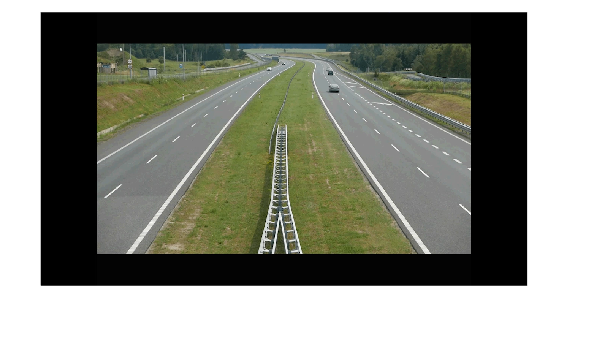

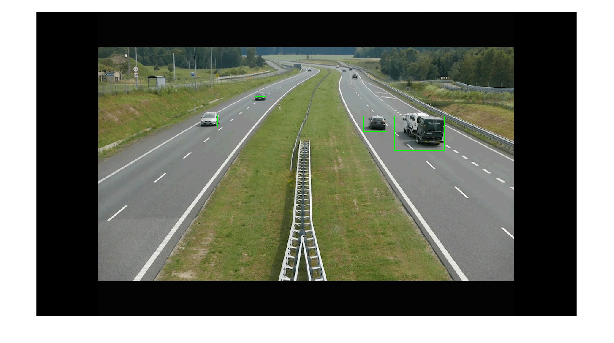

figure(), hold on
mu_plot = scatter([], [],100,'x','red');

for timestep = 1:n_timesteps
    % Do an iteration of JPDA Filter for confirmed tracks
    tau = size(mu,2);
    u = zeros(n_inp,tau);
    [mu, sigma, ~, beta_auxillary, z_nc] = iterate(mu, sigma, u, z{timestep});
    
    dbstop if warning

    % Remove targets that have died
    [~, purge, c_tracker] = check_promotion(beta_auxillary, c_tracker);
    
    if ~isempty(purge)
        mu = mu(:,~purge);
        sigma = sigma(:,:,~purge);
        c_tracker = c_tracker(:,~purge);
    end

    % Do an iteration of JPDA Filter for tentative tracks
    tau = size(mu_tentative,2);
    u = zeros(n_inp,tau);
    [mu_tentative, sigma_tentative, ~, beta_auxillary, z_nt] = iterate(mu_tentative, sigma_tentative, u, z_nc);
    
    % Promote tentative tracks that meet M/N to confirmed, purge otherwise
    [promote, purge, t_tracker] = check_promotion(beta_auxillary, t_tracker);
    mu = cat(2, mu, mu_tentative(:,promote));
    sigma = cat(3, sigma, sigma_tentative(:,:,promote));
    c_tracker = cat(2, c_tracker, zeros(N+1,sum(promote)));
    
    if ~isempty([purge, promote])
        mu_tentative = mu_tentative(:,~[purge, promote]);
        sigma_tentative = sigma_tentative(:,:,~[purge, promote]);
        t_tracker = t_tracker(:,~[purge, promote]);
    end
    
    % Promote new tracks that meet second measurement
    [mu_promoted, z_nn] = check_promotion_new(mu_new,z_nt);
    
    mu_tentative = cat(2, mu_tentative, mu_promoted);
    sigma_tentative = cat(3, sigma_tentative, repmat(1*R,[1,1,size(mu_promoted,2)]));
    tracker_init = zeros(N+1,1);
    tracker_init(end) = -1;
    t_tracker = cat(2, t_tracker, repmat(tracker_init,[1,size(mu_promoted,2)]));

    % Residual measurements are turned into new tracks
    mu_new = z_nn;

    % Plot new frame
    plotCars(readFrame(video), bboxes{timestep},mu,sigma)
end

### Visualise

function [] = plotCars(frame, bboxes, mu, sigma)
    detection = insertShape(frame, 'Rectangle', bboxes, 'Color', 'green');
    imshow(detection)
    mu_plot.XData = mu(1,:);
    mu_plot.YData = mu(2,:);
    drawnow
end

function [plotX, plotY] = plotErrorEllipse(mu, Sigma, p)
    % Helper function for plotting uncertainty bounds
    s = -2 * log(1 - p);
    [V, D] = eig(Sigma * s);
    t = linspace(0, 2 * pi);
    a = (V * sqrt(D)) * [cos(t(:))'; sin(t(:))'];

    plotX = a(1, :) + mu(1);
    plotY = a(2, :) + mu(2);
end